# Waste Analysis Demo

Use the `ThermoeconomicModel` function to perform a waste analysis

### **Create the Thermoeconomic Model**

file="D:\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
model=ThermoeconomicModel(file,'DiagnosisMethod','NONE','Debug',false);

### Show the results for the reference state

Show the direct unit cost table values

showResults(model,'dfcost');


Flows Exergy Cost - REF

Key          B(kW)      B*(kW)     Be*(kW)     Br*(kW)     k*(J/J)    ke*(J/J)    kr*(J/J)
———————————————————————————————————————————————————————————————————————————————————————————
B1          83.570     133.485     115.091      18.394      1.5973      1.3772      0.2201
B2          17.900      28.591      24.652       3.940      1.5973      1.3772      0.2201
B3          15.790      25.221      21.746       3.476      1.5973      1.3772      0.2201
B4           5.784       9.239       7.966       1.273      1.5973      1.3772      0.2201
B5           7.877      14.133      12.185       1.948      1.7942      1.5469      0.2472
B6           9.420      17.503      15.091       2.412      1.8581      1.6020      0.2560
QBLR       100.000     100.000     100.000       0.000      1.0000      1.0000      0.0000
WP           2.447       4.894       4.220       0.674      2.0000      1.7244      0.2756
WN          50.000     100.000      86.220      13.780      2.0

### Define Waste Analysis Parameters

Perform a waste analysis for State noIHE (without IHE), recycling 40% of heat in the conderser,

model.setState('noIHE');
model.setActiveWaste('QCND');
model.setWasteType('HYBRID');
model.setWasteRecycled(0.4);

#### Show Waste Allocation Graph

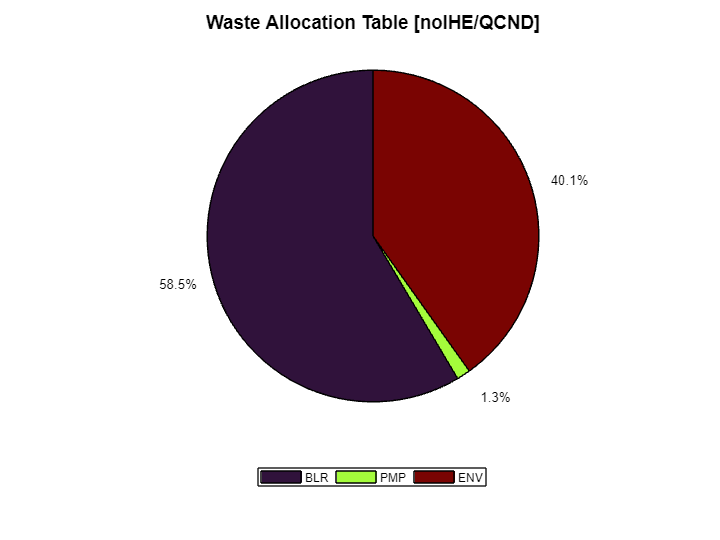

ShowGraph(model,'Graph',cType.Tables.WASTE_ALLOCATION);

####  Show cost values and graphs for the study case (noIHE)

showResults(model,'ducost')

Process Unit Exergy Cost - noIHE

Key      kP*(J/J)   kPe*(J/J)   kPr*(J/J)    kF*(J/J)    kR*(J/J)      k(J/J)
——————————————————————————————————————————————————————————————————————————————
BLR        1.5602      1.4123      0.1479      1.0000      0.1479      1.4123
TRB        1.9845      1.7913      0.1931      1.5839      0.0013      1.2521
IHE        0.0000      0.0000      0.0000      0.0000      0.0000      1.0000
PMP        2.4418      2.0943      0.3475      1.9845      0.1217      1.1691
CND        1.5839      1.4306      0.1532      1.5839      0.0000      1.0000



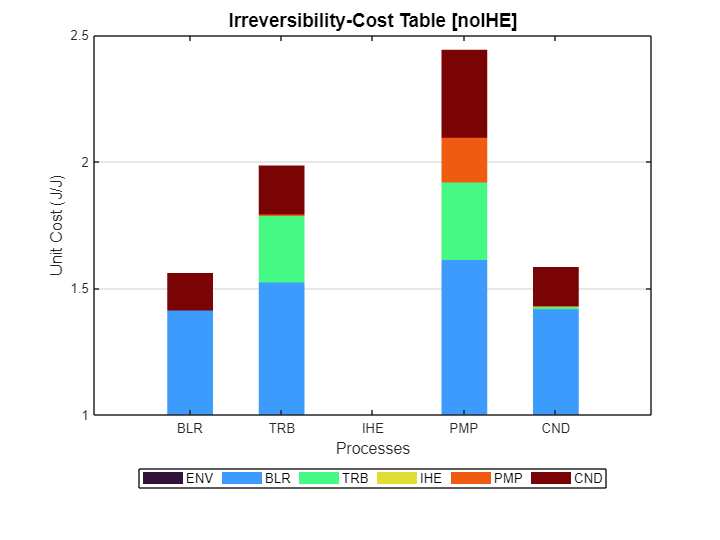

showGraph(model,cType.Tables.PROCESS_ICT);

### Recycling Analysis

Show the recycling analysis graph

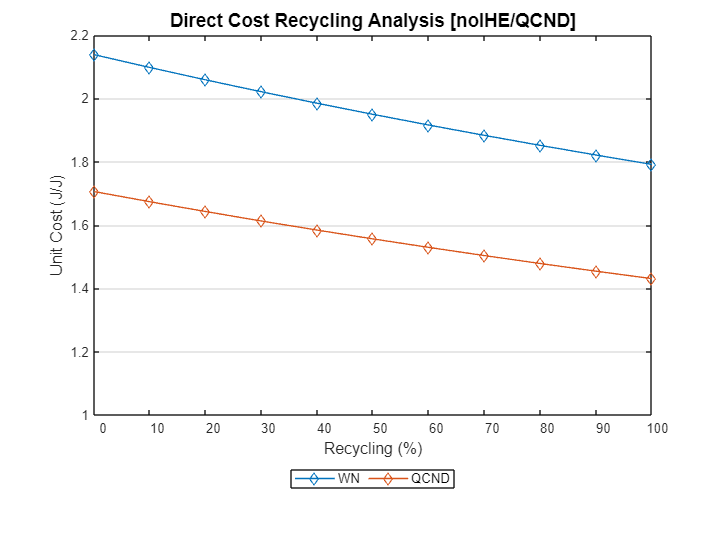

model.setRecycling(true);
showGraph(model,cType.Tables.WASTE_RECYCLING_DIRECT);